%% Project Energy Systems Analysis - Part 1
% Student: Vahid Hamzeh (402101577)

clc; clear; close all;

% System Parameters
V_nom_kV = 765;
Vr_ph = (V_nom_kV * 1000) / sqrt(3); % Phase Voltage (V)

% Line Parameters per km
R_prime = 0.045;   % Ohm/km
X_prime = 0.38;    % Ohm/km
B_prime = 2.8e-6;  % S/km

z = R_prime + 1j*X_prime;
y = 1j*B_prime;

% Table Calculations (Data for Report Tables)
Lengths_Table = [80, 120, 160, 200, 240, 280, 320, 360];
LoadCases = [160, 0.85; 220, 0.92; 260, 0.95];
CaseNames = {'Low Load', 'Nominal Load', 'High Load'};

for k = 1:size(LoadCases, 1)
    P_MW = LoadCases(k, 1);
    pf = LoadCases(k, 2);
    
    Ir_mag = (P_MW * 1e6) / (3 * Vr_ph * pf);
    theta_r = -acos(pf);
    Ir = Ir_mag * exp(1j * theta_r);
    
    fprintf('\n>>> Load Case: %s (P=%.0f MW, PF=%.2f) <<<\n', CaseNames{k}, P_MW, pf);
    fprintf('%-6s %-8s %-12s %-12s %-10s %-10s %-15s\n', 'Len', 'Model', 'Vs(kV_LL)', 'Is(A)', 'VR(%)', 'Eff(%)', 'Suggested Model');
    fprintf('--------------------------------------------------------------------------------\n');
    
    for L = Lengths_Table
        % Short Model
        Z_total = z * L;
        [Vs_s, Is_s, VR_s, Eff_s] = calc_line(1, Z_total, 0, 1, Vr_ph, Ir, P_MW);
        
        % Medium Model
        Y_total = y * L;
        A_m = 1 + (Z_total * Y_total)/2;
        C_m = Y_total * (1 + (Z_total * Y_total)/4);
        [Vs_m, Is_m, VR_m, Eff_m] = calc_line(A_m, Z_total, C_m, A_m, Vr_ph, Ir, P_MW);
        
        % Long Model
        gamma = sqrt(z * y); Zc = sqrt(z / y);
        A_l = cosh(gamma * L); B_l = Zc * sinh(gamma * L); C_l = (1/Zc) * sinh(gamma * L);
        [Vs_l, Is_l, VR_l, Eff_l] = calc_line(A_l, B_l, C_l, A_l, Vr_ph, Ir, P_MW);
        
        % Logic for Suggested Model
        err_I_short = abs(Is_s - Is_l) / Is_l * 100;
        err_I_med = abs(Is_m - Is_l) / Is_l * 100;
        
        if L < 80 && err_I_short < 5.0
            suggested = 'Short';
        elseif L <= 240 && err_I_med < 2.5
            suggested = 'Medium';
        else
            suggested = 'Long';
        end
        
        fprintf('%-6d %-8s %-12.2f %-12.2f %-10.2f %-10.2f %-15s\n', L, 'Short', Vs_s, Is_s, VR_s, Eff_s, suggested);
        fprintf('%-6s %-8s %-12.2f %-12.2f %-10.2f %-10.2f\n', '', 'Medium', Vs_m, Is_m, VR_m, Eff_m);
        fprintf('%-6s %-8s %-12.2f %-12.2f %-10.2f %-10.2f\n', '', 'Long', Vs_l, Is_l, VR_l, Eff_l);
        fprintf('--------------------------------------------------------------------------------\n');
    end
end


>>> Load Case: Low Load (P=160 MW, PF=0.85) <<<


Len    Model    Vs(kV_LL)    Is(A)        VR(%)      Eff(%)     Suggested Model


--------------------------------------------------------------------------------


80     Short    769.72       142.06       0.62       99.86      Medium         


       Medium   767.11       122.77       0.62       99.90     


       Long     767.11       122.79       0.62       99.89     


--------------------------------------------------------------------------------


120    Short    772.09       142.06       0.93       99.80      Medium         


       Medium   766.24       140.67       0.94       99.85     


       Long     766.23       140.79       0.93       99.83     


--------------------------------------------------------------------------------


160    Short    774.48       142.06       1.24       99.73      Medium         


       Medium   764.08       171.12       1.26       99.80     


       Long     764.05       171.48       1.25       99.75     


--------------------------------------------------------------------------------


200    Short    776.87       142.06       1.55       99.66      Medium         


       Medium   760.64       208.43       1.59       99.71     


       Long     760.60       209.21       1.58       99.63     


--------------------------------------------------------------------------------


240    Short    779.28       142.06       1.87       99.59      Medium         


       Medium   755.91       249.21       1.94       99.60     


       Long     755.86       250.64       1.91       99.45     


--------------------------------------------------------------------------------


280    Short    781.70       142.06       2.18       99.53      Long           


       Medium   749.92       291.66       2.29       99.43     


       Long     749.86       293.99       2.26       99.21     


--------------------------------------------------------------------------------


320    Short    784.13       142.06       2.50       99.46      Long           


       Medium   742.65       334.76       2.67       99.20     


       Long     742.61       338.30       2.61       98.88     


--------------------------------------------------------------------------------


360    Short    786.57       142.06       2.82       99.39      Long           


       Medium   734.11       377.91       3.06       98.91     


       Long     734.12       382.99       2.98       98.45     


--------------------------------------------------------------------------------



>>> Load Case: Nominal Load (P=220 MW, PF=0.92) <<<


Len    Model    Vs(kV_LL)    Is(A)        VR(%)      Eff(%)     Suggested Model


--------------------------------------------------------------------------------


80     Short    769.80       180.47       0.63       99.84      Medium         


       Medium   767.20       167.89       0.63       99.86     


       Long     767.20       167.90       0.63       99.86     


--------------------------------------------------------------------------------


120    Short    772.24       180.47       0.95       99.76      Medium         


       Medium   766.39       182.20       0.96       99.80     


       Long     766.38       182.31       0.95       99.78     


--------------------------------------------------------------------------------


160    Short    774.70       180.47       1.27       99.68      Medium         


       Medium   764.31       207.22       1.29       99.72     


       Long     764.28       207.54       1.28       99.69     


--------------------------------------------------------------------------------


200    Short    777.18       180.47       1.59       99.60      Medium         


       Medium   760.96       239.38       1.63       99.63     


       Long     760.91       240.10       1.62       99.57     


--------------------------------------------------------------------------------


240    Short    779.68       180.47       1.92       99.52      Medium         


       Medium   756.34       275.90       1.99       99.51     


       Long     756.28       277.25       1.97       99.41     


--------------------------------------------------------------------------------


280    Short    782.20       180.47       2.25       99.44      Long           


       Medium   750.47       314.94       2.37       99.35     


       Long     750.39       317.18       2.33       99.19     


--------------------------------------------------------------------------------


320    Short    784.74       180.47       2.58       99.36      Long           


       Medium   743.34       355.31       2.77       99.15     


       Long     743.27       358.75       2.70       98.92     


--------------------------------------------------------------------------------


360    Short    787.30       180.47       2.92       99.29      Long           


       Medium   734.97       396.24       3.18       98.89     


       Long     734.92       401.23       3.09       98.57     


--------------------------------------------------------------------------------



>>> Load Case: High Load (P=260 MW, PF=0.95) <<<


Len    Model    Vs(kV_LL)    Is(A)        VR(%)      Eff(%)     Suggested Model


--------------------------------------------------------------------------------


80     Short    769.68       206.55       0.61       99.82      Medium         


       Medium   767.08       198.59       0.61       99.84     


       Long     767.08       198.61       0.61       99.84     


--------------------------------------------------------------------------------


120    Short    772.07       206.55       0.92       99.73      Medium         


       Medium   766.23       212.06       0.93       99.76     


       Long     766.21       212.16       0.93       99.75     


--------------------------------------------------------------------------------


160    Short    774.49       206.55       1.24       99.65      Medium         


       Medium   764.11       234.92       1.26       99.67     


       Long     764.08       235.22       1.26       99.65     


--------------------------------------------------------------------------------


200    Short    776.95       206.55       1.56       99.56      Medium         


       Medium   760.74       264.53       1.60       99.57     


       Long     760.69       265.22       1.59       99.52     


--------------------------------------------------------------------------------


240    Short    779.43       206.55       1.89       99.47      Medium         


       Medium   756.12       298.62       1.96       99.44     


       Long     756.05       299.91       1.94       99.35     


--------------------------------------------------------------------------------


280    Short    781.94       206.55       2.21       99.38      Long           


       Medium   750.25       335.50       2.34       99.27     


       Long     750.16       337.68       2.30       99.15     


--------------------------------------------------------------------------------


320    Short    784.48       206.55       2.55       99.30      Long           


       Medium   743.15       374.02       2.74       99.07     


       Long     743.05       377.39       2.67       98.89     


--------------------------------------------------------------------------------


360    Short    787.06       206.55       2.88       99.21      Long           


       Medium   734.81       413.34       3.16       98.83     


       Long     734.73       418.26       3.07       98.57     


--------------------------------------------------------------------------------


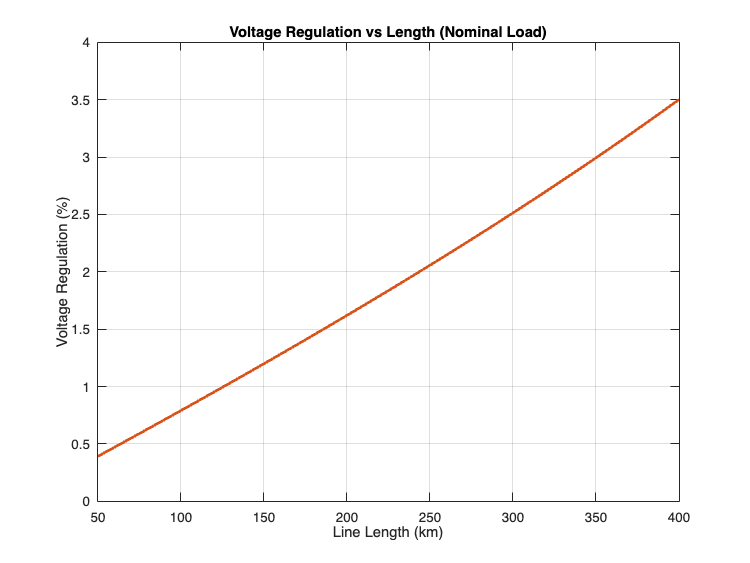


% Plotting Set 1: VR & Efficiency vs Length
L_range = 50:5:400;
VR_len_data = zeros(size(L_range));
Eff_len_data = zeros(size(L_range));

% Nominal Load Parameters
P_nom = 220; pf_nom = 0.92;
Ir_mag = (P_nom * 1e6) / (3 * Vr_ph * pf_nom);
Ir = Ir_mag * exp(1j * -acos(pf_nom));

for i = 1:length(L_range)
    L = L_range(i);
    gamma = sqrt(z * y); Zc = sqrt(z / y);
    A = cosh(gamma * L); B = Zc * sinh(gamma * L);
    C = (1/Zc) * sinh(gamma * L); D = A;
    
    [~, ~, vr, eff] = calc_line(A, B, C, D, Vr_ph, Ir, P_nom);
    VR_len_data(i) = vr;
    Eff_len_data(i) = eff;
end

% Plot 1: VR vs Length
figure('Name', 'VR vs Length', 'Color', 'w');
plot(L_range, VR_len_data, 'LineWidth', 2, 'Color', [0.85, 0.33, 0.1]); 
grid on; xlabel('Line Length (km)'); ylabel('Voltage Regulation (%)');
title('Voltage Regulation vs Length (Nominal Load)');

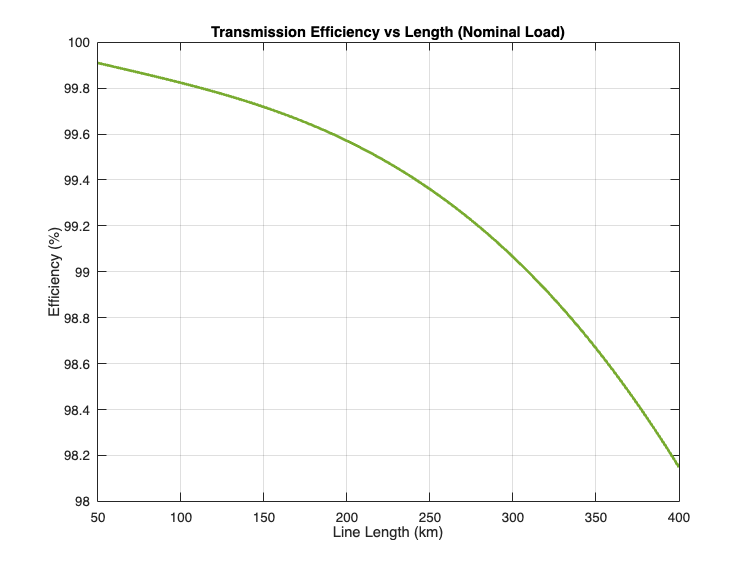


% Plot 2: Efficiency vs Length
figure('Name', 'Efficiency vs Length', 'Color', 'w');
plot(L_range, Eff_len_data, 'LineWidth', 2, 'Color', [0.47, 0.67, 0.19]);
grid on; xlabel('Line Length (km)'); ylabel('Efficiency (%)');
title('Transmission Efficiency vs Length (Nominal Load)');

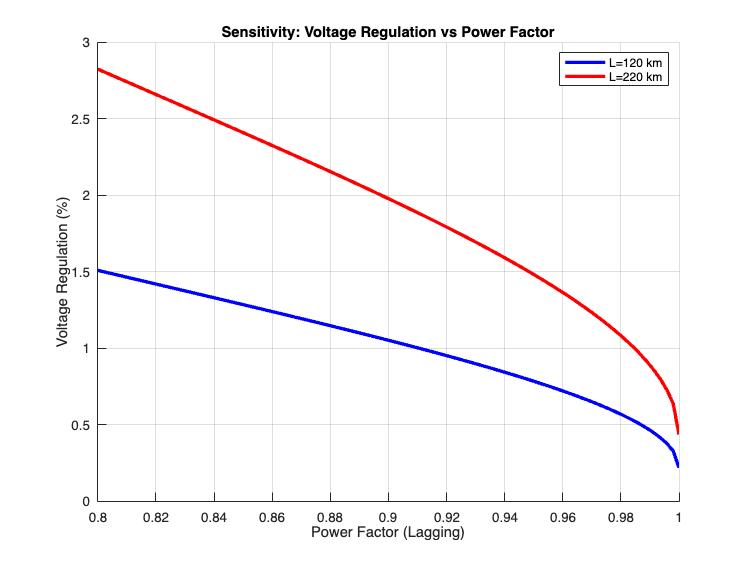


% Plotting Set 2: VR vs Power Factor
pf_range = 0.8 : 0.002 : 1.0;
L_cases_plot = [120, 220]; % Matches instruction requirement exactly
colors = {'b', 'r'};

figure('Name', 'VR vs Power Factor', 'Color', 'w'); hold on; grid on;

for j = 1:length(L_cases_plot)
    L = L_cases_plot(j);
    vr_pf_data = zeros(size(pf_range));
    
    gamma = sqrt(z * y); Zc = sqrt(z / y);
    A = cosh(gamma * L); B = Zc * sinh(gamma * L);
    
    for k = 1:length(pf_range)
        pf = pf_range(k);
        Ir_loc = ((P_nom*1e6)/(3*Vr_ph*pf)) * exp(1j*-acos(pf));
        
        Vs = A*Vr_ph + B*Ir_loc;
        vr_pf_data(k) = ((abs(Vs)/abs(A)) - Vr_ph)/Vr_ph * 100;
    end
    
    plot(pf_range, vr_pf_data, 'LineWidth', 2.5, 'Color', colors{j}, ...
        'DisplayName', sprintf('L=%d km', L));
end

xlabel('Power Factor (Lagging)'); 
ylabel('Voltage Regulation (%)');
title('Sensitivity: Voltage Regulation vs Power Factor');
legend('show', 'Location', 'northeast');
xlim([0.8 1.0]);


% Helper Function
function [Vs_LL_kV, Is_mag, VR, Eff] = calc_line(A, B, C, D, Vr_ph, Ir, P_MW)
    Vs = A * Vr_ph + B * Ir;
    Is = C * Vr_ph + D * Ir;
    
    Vs_LL_kV = abs(Vs) * sqrt(3) / 1000;
    Is_mag = abs(Is);
    
    VR = ( (abs(Vs)/abs(A)) - Vr_ph ) / Vr_ph * 100;
    
    P_in = real(3 * Vs * conj(Is));
    P_out = P_MW * 1e6;
    if P_in > 0
        Eff = (P_out / P_in) * 100;
    else
        Eff = 0;
    end
end